# Plantilla Simulink

**Limpieza del entorno de trabajo**

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

**Resumen**

Este script configura los principales parámetros de simulación, dibujo y etiquetas de un modelo discreto para su posterior ejecución y análisis.

### 1. Planteamiento

Ecuación del modelo: $Fib\left(n+1\right)=Fib\left(n\right)+Fib\left(n-1\right)$

Condiciones iniciales: $Fib\left(0\right)=0;\;Fib\left(1\right)=1$

Inicio: $n_0 =0$    Fin: $n_1 =5$ (por ejemplo)

### 2. Configuración usuario

Constantes del modelo

% Initial conditions
F0 = 0; % F(0) = 0
F1 = 1; % F(1) = 1

% Global constants
% Example: g = 9.8

Nombre del modelo

model_name = "modelo_fibonacci";

Configuración del solver

solver = struct();
solver.type = "Fixed-Step";
solver.name = "FixedStepDiscrete";
solver.start = 0;
solver.stop = 5;
solver.step = 1;

Configuración dibujos gráfica

graph = "scatter"; % draw function used

% scatter settings
sc = struct();
sc.sz = 200; % size
sc.mkr = "."; % marker
sc.transparency = 0.5; % transparency

% plot settings
pl = struct();
pl.linespec = "-"; % linestyle/marker/color
pl.mkr.sz = 12; % marker size

Configuración etiquetas gráfica

labels = struct();
% xlabel settings
labels.x.name = "n"; 
labels.x.interpreter = "latex";

% ylabel settings
labels.y.name = "Fib(n)";
labels.y.interpreter = "latex";

% title settings
labels.title.name = "Simulación Fibonacci";
labels.title.interpreter = "none";

### 3. Ejecución simulación

Al final de este livescript se encuentra la definición de la función sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output (véase consideraciones adicionales Simulink al final de este LiveScript)

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout; % Dataset container of signals
num_signals = numElements(signals); % Number of signals

Se dibuja cada señal

% Draw each signal
hold on
for i = 1:num_signals
    signal = signals{i}.Values;
    if graph == "scatter"
        scatter(signal.Time, signal.Data, sc.sz, sc.mkr, ...
            MarkerEdgeAlpha=string(sc.transparency), ...
            DisplayName=signal.Name);
    elseif graph == "plot"
        plot(signal.Time, signal.Data, pl.linespec, ...
            MarkerSize=pl.mkr.sz, ...
            DisplayName=signal.Name);
    elseif graph == "none"
        break
    else
        break
    end
end
grid on

Límites y leyenda

xlim([signal.Time(1), signal.Time(end)]);
legend('show','location','best');

Al final de este livescript se define la función set_labels que crea las etiquetas a partir de la configuración

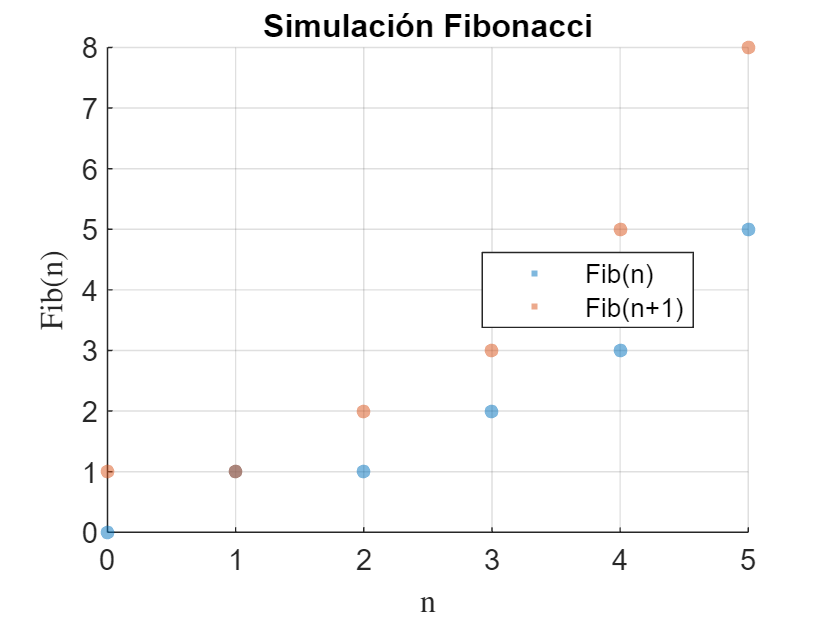

set_labels(labels)
hold off

### ***Funciones disponibles para todas las secciones***

MATLAB permite utilizar la última sección de un livescript para definir funciones globales.

#### *Decorador de la función sim de MATLAB

Esta función ejecuta la función sim, tras establecer los parámetros del solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

function sim_data = sim_config(model_name, solver)

Carga del modelo con load_system

load_system(model_name)
% open_system(model_name) will also open it

Configuración con set_param

% Set solver parameters
set_param(model_name, ...
    SolverType  = solver.type, ...
    SolverName  = solver.name, ...
    StartTime   = string(solver.start),...
    StopTime    = string(solver.stop), ...
    FixedStep   = string(solver.step) ...
    )
% More model parameters can be retrieved with:
% model_data = get_param(model_name, "ObjectParameters")
% Access blocks params with "model_name/block_name"

Simulación del modelo con sim

sim_data = sim(model_name);
% SimulationMode="normal" by default
end

#### *Configuración xlabel, ylabel, title de MATLAB

Esta función configura las etiquetas de la figura actual. Recibe una variable struct con la configuración de las etiquetas.

function set_labels(labels)
title(labels.title.name, Interpreter=labels.title.interpreter)
xlabel(labels.x.name, Interpreter=labels.x.interpreter);
ylabel(labels.y.name, Interpreter=labels.y.interpreter);
end

#### Consideraciones adicionales Simulink

Se utiliza el bloque Out1 para cada señal debido a que:

- No usaremos bloques Bus para no formatear los nombres, ejemplo: MATLAB transforma '+' a '_'

- No usaremos bloques To Workspace para iterar más fácil, iteramos el contenido de .yout

- Es posible el manejo de múltiples condiciones iniciales sin problema

#### Scripts adicionales

Para obtener cada señal se puede usar: 

% signals{index}
% signals.getElement('signal_name')

Los valores de una señal se encuentran en el campo Values

% signals{index}.Values.Data
% signals{index}.Values.Time
% signals{index}.Values.Name

Inicio y fin de una señal

% sim_data = sim_config(model_name, solver)
% signals = sim_data.yout
%
% start_value = signals{1}.Values.Data(1);
% end_value = signals{1}.Values.Data(end);

Máximo y mínimo de una señal

% sim_data = sim_config(model_name, solver)
% signals = sim_data.yout
%
% [signal_max, index_max] = max(signals{1}.Values.Data);
% point_max = [signals{1}.Values.Time(index_max), signal_max];
%
% [signal_min, index_min] = min(signals{1}.Values.Data);
% point_min = [signals{1}.Values.Time(index_min), signal_min];

Media de una señal

% sim_data = sim_config(model_name, solver)
% signals = sim_data.yout
%
% signal_mean = mean(signals{1}.Values.Data)

Autor: Alfredo Robledano Abasolo 3ºB Ingeniería Matemática UFV (2023-2024)